clc; clear; close all;

C = 27;
d = 4;

n = 100;
h = 1/(n-1);

% f = @(x, y) exp(x.^2 + y.^2).*sin(x)

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

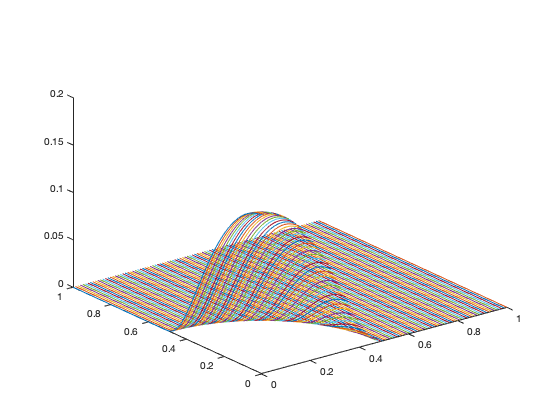

D_mesh = transpose(linspace(0, 1, n));
[X, Y] = meshgrid(D_mesh);

f_xy = f(X, Y);

figure;
plot3(X, Y, f_xy)

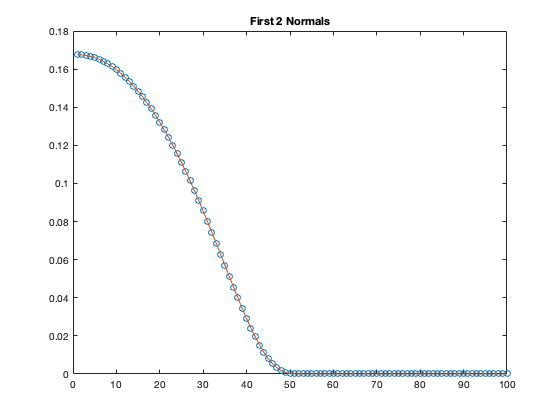


figure;
plot(f_xy(:, 1), 'o');
hold on;
plot(f_xy(:, 2));
title("First 2 Normals")

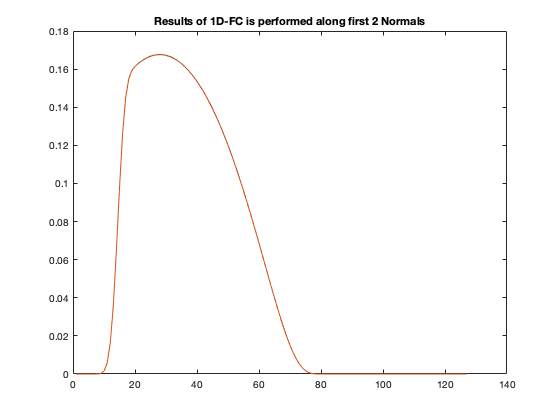


fcont = fcont_gram_blend_S(f_xy(:,1:2), d, A, Q);
figure;
plot(fcont(:, 1));
hold on;
plot(fcont(:, 2));
title("Results of 1D-FC is performed along first 2 Normals")

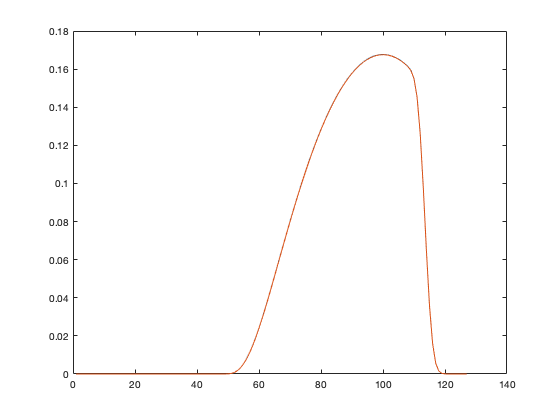


cont_D_mesh = transpose(-C*h:h:1);
[CONT_X, CONT_Y] = meshgrid(D_mesh(1:2), cont_D_mesh);

[~, fcont_1, ~, ~] = fcont_gram_blend(flipud(f_xy(:, 1)), d, C, A, Q, Q);
[~, fcont_2, ~, ~] = fcont_gram_blend(flipud(f_xy(:, 2)), d, C, A, Q, Q);

figure;
plot(fcont_1)
hold on;
plot(fcont_2)

function f_y = f(x, y)
    r = sqrt(x.^2 + y.^2);
    f_y = zeros(size(x));
    f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
    f_y(r >= 0.56) = 0;
end